# Impedance matching considering electrical power

## from Strofer et al 2023: CCD of PTOs with WecOptTool

% 
% syms Z_i Z_fu Z_fi Z_vu Z_vi complex
% syms F_e real
% 
% V_th = Z_vu / (Z_i - Z_fu) * F_e;
% Z_th = Z_vi + (Z_fi * Z_vu) / (Z_i - Z_fu);
% Z_abcd = [- Z_fi \ Z_fu, inv(Z_fi);
%           Z_vu - Z_vi / Z_fi * Z_fu, Z_vi \ Z_fi];
% 
% IV_opt = [-1; conj(Z_th)] * V_th / (2 * real(Z_th));
% UF_opt = Z_abcd \ IV_opt;
% Zp_opt = ([0 1] * UF_opt) / ([1 0] * UF_opt)
% 
% simplify(Zp_opt)
% 

## Retry

% clear all
% syms Z_d Z_w Z_i complex
% syms K_t N_d F_e real positive
% 
% Z_fu = -N_d^2 * Z_d;
% Z_fi = -sqrt(3/2)*K_t * N_d;
% Z_vu = -sqrt(3/2)*K_t * N_d;
% Z_vi = Z_w;
% 
% V_th = Z_vu / (Z_i - Z_fu) * F_e;
% Z_th = Z_vi + (Z_fi * Z_vu) / (Z_i - Z_fu);
% Z_abcd = [- Z_fi \ Z_fu, inv(Z_fi);
%           Z_vu - Z_vi / Z_fi * Z_fu, Z_vi \ Z_fi];
% 
% IV_opt = [-1; conj(Z_th)] * V_th / (2 * real(Z_th));
% UF_opt = Z_abcd \ IV_opt;
% Zp_opt = ([0 1] * UF_opt) / ([1 0] * UF_opt)
% 
% simplify(Zp_opt)

## MASK basin workshop slides p153 - conversion efficiency

% syms Z_L complex
% Z_11 = Z_fu; Z_12 = Z_fi;
% Z_21 = Z_vu; Z_22 = Z_vi;
% fraction = Z_21 / ( (Z_11 + Z_i)*(Z_22 + Z_L) - Z_12*Z_21)
% eta = 4 * real(Z_i) * real(Z_L) * abs(fraction)^2;
% 
% % sensitivity
% can_change = [N_d, Z_d, K_t, Z_L];
% J = gradient(eta,can_change)
% assume(real(Z_i),'positive')
% assume(real(Z_L),'positive')
% conds = simplify(J==0)
% conds134 = simplify(conds(1) & conds(3) & conds(4),100)
% allConds = simplify(conds134 & conds(2), 100)
% 

## Phase of different variables, as in MASK workshop slide 77

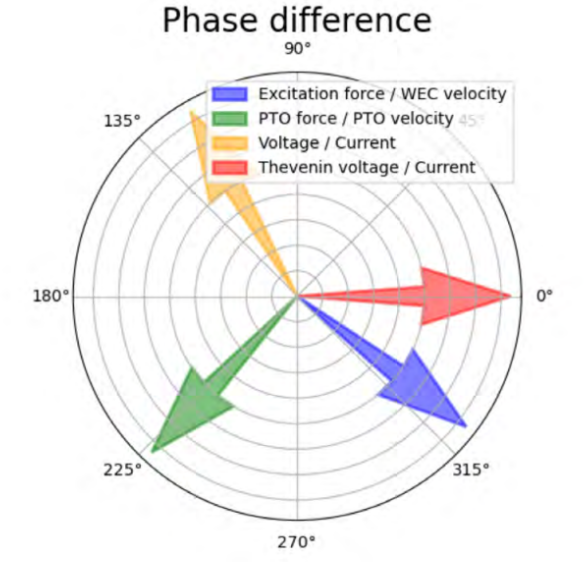

% clear all
% syms w m B_h B_pto N_d K_h K_t B_w L_w real positive
% syms K_pto B_g K_g real
% s = 1i * w;
% B_eff = B_h + N_d^2 * B_pto;
% K_eff = K_h + N_d^2 * K_pto;
% Z_w = B_w + s * L_w;
% K_m = sym(sqrt(3/2)) * K_t * N_d;
% X_over_F = 1/(m*s^2 + B_eff*s + K_eff)
% Vbemf_over_X = s * K_m;
% Vw_over_Fgen = Z_w / K_m;
% % never ended up computing phase and making the arrows but the var definitions are used in the
% % cell below

## Max electrical power based on p64 of notebook

% % this assumes Lw = 0
% syms zeta_u w_n_u real positive
% X_over_F = 1/m * 1/(s^2 + 2*zeta_u*w_n_u * s + w_n_u^2);
% 
% P_Fh2 = (X_over_F / (1/ (B_g * s + K_g) + X_over_F))^2 * (B_w/K_m^2 - s/(B_g*s + K_g));
% eqn = diff(P_Fh2, K_g) == 0;
% eqn2 = diff(P_Fh2, B_g) == 0;
% sol = solve([eqn,eqn2],[K_g,B_g]);
% Kg_opt = simplify(sol.K_g);
% Bg_opt = simplify(sol.B_g);
% 
% syms w_star_u real positive
% Kg_opt = simplify(subs(Kg_opt, w_n_u, w / w_star_u))
% Bg_opt = simplify(subs(Bg_opt, w_n_u, w / w_star_u))
% % this matches biconjugate matching from slides, see notebook p67-69
% 
% % power for saturated-optimal control for any given wec + pto
% syms m_sat real positive % multiplier compared to optimal
% P_Fh2mw = P_Fh2 * w * m;
% P_Fh2mw_opt = subs(P_Fh2mw,{B_g,K_g},m_sat*{Bg_opt,Kg_opt});
% P_Fh2mw_opt = simplify(subs(P_Fh2mw_opt, w_n_u, w / w_star_u));
% 
% % define nondimensional resistance R* = 2 * m * w * Bw / (3 * Kt^2 * Nd^2) to condense Bw, Kt, Nd, m, w into 1 param
% syms R real positive
% P_Fh2mw_opt = simplify(subs(P_Fh2mw_opt, B_w, 3/2 * R * K_t^2 * N_d^2 / (m * w)))
% P_Fh2wm_opt_avg = simplify(real(P_Fh2mw_opt))
% 
% % this nondimensional power is just a fcn of c, m_sat, w_star_u, and zeta_u
% R_vec = [0, 0.1, 1];
% m_vec = [0.5, 1];
% figure
% for i = 1:length(R_vec)
%     for j = 1:length(m_vec)
%         R_val = R_vec(i);
%         m_val = m_vec(j);
%         subplot(length(m_vec), length(R_vec), i+length(R_vec)*(j-1))
%         fcn = subs(P_Fh2wm_opt_avg, {R,m_sat}, {R_val,m_val});
%         fcontour(fcn, [0,2,0,0.5], 'fill',true, ...
%             'LevelList',[-4,-3,-2,-1,-0.75,-0.5,-0.25,-0.1,0])
%         title(['R^* = ',num2str(R_val),', m_{sat} = ',num2str(m_val)])
%         xlabel('\omega_u^*')
%         ylabel('\zeta_u')
%         colorbar
%         grid on
%         set(gca,'layer','top'); % make gridlines visible
%         caxis([-4 0])
%     end
% end
% % Conclusion: assuming negative power is generation, the trend makes sense
% % that w_star_u = 1 is optimal, and that higher resistance (c) gives less
% % power. I don't understand why zeta_u = 0 (undamped) appears optimal.
% 
% Kg_opt_noR = subs(Kg_opt,B_w,0)
% Bg_opt_noR = subs(Bg_opt,B_w,0)

## Compute m_sat for generic off-matched impedance

% % Using page 70-71 in notebook
% clear all
% syms a b real % a = real(Zth), b = imag(Zth)
% syms m_sat real positive
% 
% % flow limited (current)
% i_sat = 2*a / sqrt( (1+m_sat)^2*a^2 + (1-m_sat)^2*b^2 )
% m_sat_flow = solve(i_sat,m_sat)
% % idk why this can't solve, did it by hand on p75 and result is below
% syms isat
% sqroot = sqrt( ((a^2-b^2)/(a^2+b^2))^2 - 1 + 4*a^2/(isat^2 * (a^2+b^2)) )
% m_sat_flow_plus = (b^2-a^2)/(b^2+a^2) + sqroot
% m_sat_flow_minus = (b^2-a^2)/(b^2+a^2) - sqroot
% 
% % effort limited (voltage)
% v_sat = 2*a/sqrt(a^2+b^2) * m_sat * sqrt(((1+m_sat)*a^2 - (1-m_sat)*b^2)^2 + (2*a*b*m_sat)^2) / ((1+m_sat)^2*a^2 + (1-m_sat)^2*b^2)
% m_sat_effort = solve(v_sat,m_sat)
% 
% % try again:
% syms vsat real positive
% eqn = (a^2+b^2)*vsat^2/(4*a) == m_sat^2 * ( (a^2*(1+m_sat) - b^2*(1-m_sat))^2 + (2*a*b*m_sat)^2 ) / ((1+m_sat)^2*a^2 + (1-m_sat)^2*b^2)^2;
% m_sat_effort = solve(eqn,m_sat,'ReturnConditions',true)
% 
% m_sat_effort = m_sat_effort.conditions
% 
% % plug in numbers for a, b, isat, vsat
% i_vec = [0.5, 0.75, 0.9];
% v_vec = [0.5, 0.75, 1];
% figure
% for i = 1:length(i_vec)
%     i_val = i_vec(i);
%     subplot(1, length(i_vec), i)
%     fcn = subs(m_sat_flow_minus, isat, i_val);
%     fcontour(fcn, [0,1], 'fill',true)
%     title(['i_{sat} = ',num2str(i_val)])
%     xlabel('a')
%     ylabel('b')
%     colorbar
%     grid on
%     set(gca,'layer','top'); % make gridlines visible
%     %caxis([0 1])
% end
% sgtitle('m_{sat} for flow limiting')
% figure
% for i = 1:length(v_vec)
%     v_val = v_vec(i);
%     subplot(1, length(v_vec), i)
%     fcn = subs(m_sat_effort, isat, v_val);
%     fcontour(fcn, [0,1], 'fill',true)
%     title(['v_{sat} = ',num2str(v_val)])
%     xlabel('a')
%     ylabel('b')
%     colorbar
%     grid on
%     set(gca,'layer','top'); % make gridlines visible
%     %caxis([-4 0])
% end
% sgtitle('m_{sat} for effort limiting')

## Power equation verification

% % eqn on page 80 of notebook
% clear all
% syms m_sat Z_th
% P_Vth2 = 1/2 * real(m_sat * Z_th') / ( abs(Z_th)^2 + abs(m_sat * Z_th')^2 + 2*real(m_sat * Z_th'^2) );
% P_opt_Vth2 = 1/(8 * real(Z_th));
% 
% gamma = (m_sat - 1)/(m_sat+1);
% 
% P_ratio = P_Vth2 / P_opt_Vth2;
% hopeTrue = P_ratio == 1 - abs(gamma)^2
% simplify(hopeTrue,500)
% 
% figure
% ZMIN = 0; ZMAX = 1; MMIN = 0; MMAX = 1;
% fcontour(P_Vth2,[ZMIN ZMAX MMIN MMAX])
% xlabel('Re(Z_{th})')
% ylabel('Re(m_{sat})')
% title('P / V_{th}^2')
% colorbar
% 
% figure
% ZMIN = 0; ZMAX = 1; MMIN = 0; MMAX = 1;
% fcontour(P_ratio,[ZMIN ZMAX MMIN MMAX])
% xlabel('Re(Z_{th})')
% ylabel('Re(m_{sat})')
% title('P ratio')
% colorbar
% 
% figure
% fplot(subs(P_ratio,Z_th,0.5),[MMIN MMAX])
% xlabel('Re(m_{sat})')
% title('P ratio for Z_{th}=0.5')
% 
% figure
% fplot(subs(P_ratio,Z_th,1+0.5*1i),[MMIN MMAX])
% xlabel('Re(m_{sat})')
% title('P ratio for Z_{th}=1+0.5 i')
% 
% figure
% fplot(1 - abs(gamma)^2,[MMIN MMAX])
% xlabel('Re(m_{sat})')
% title('1-|\gamma|^2')

## Derive analytical expression for voltageRatio

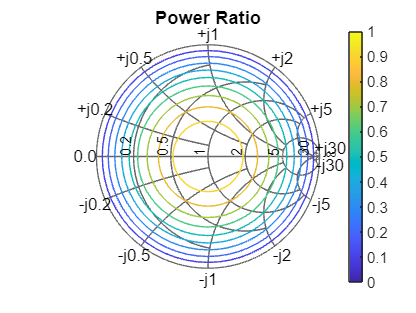

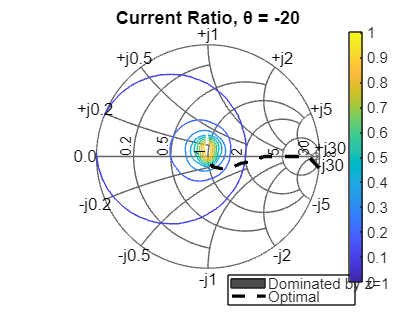

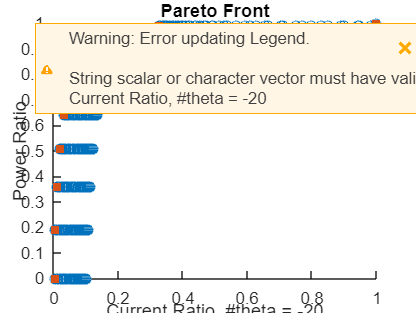

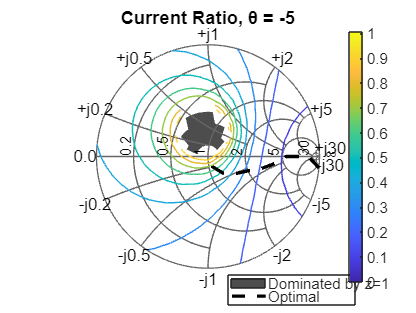

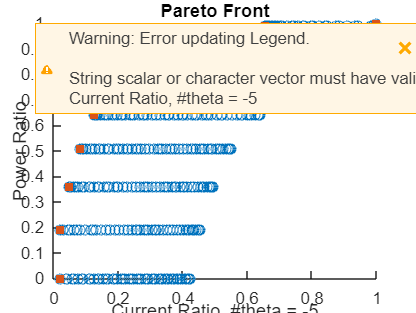

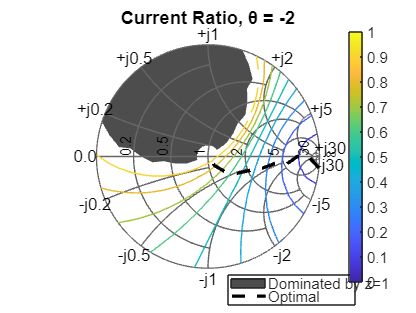

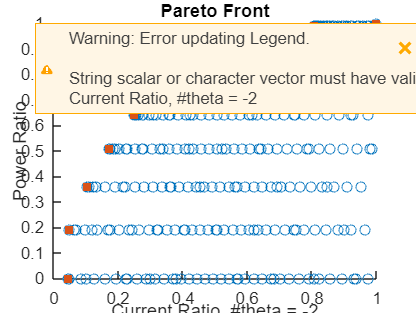

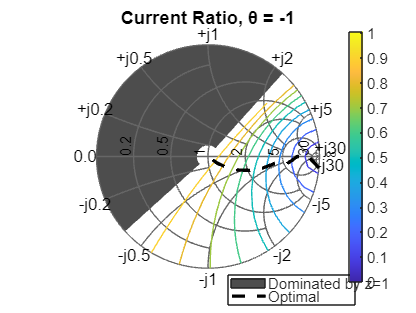

clear all

syms z1 z2 b_a real
z = z1 + 1i * z2;
complex_term = z * (1 - b_a * 1i) ./ (1 + z + (1 - z)*b_a*1i);
voltageRatio = 2/sqrt(1 + b_a^2) * abs(complex_term);
voltageRatio = simplify(voltageRatio)

syms g_mag g_ang real
gamma = g_mag * exp(1i*g_ang);

$$voltageRatio = \frac{2\,\sqrt{{z_{1}}^{2}+{z_{2}}^{2}}}{\sqrt{{\left(z_{1}+b_{a}\,z_{2}+1\right)}^{2}+{\left(z_{2}-b_{a}\,\left(z_{1}-1\right)\right)}^{2}}}$$

real_z_terms_of_gamma = real(-(gamma + 1) / (gamma - 1));
imag_z_terms_of_gamma = imag(-(gamma + 1) / (gamma - 1));

voltageRatio = subs(voltageRatio,{z1,z2},{real_z_terms_of_gamma,imag_z_terms_of_gamma});
voltageRatio = simplify(voltageRatio,100)

derivEqn = simplify(diff(voltageRatio,g_ang) == 0);
%secondDeriv = diff(voltageRatio,g_ang,2);

$$voltageRatio = \frac{\sqrt{{g_{\mathrm{mag}}}^{2}+2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sqrt{{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,b_{a}\,g_{\mathrm{mag}}+1}}$$

assume(g_mag,'positive')
%assume(secondDeriv,'positive')
g_ang_opt = solve(derivEqn,g_ang,'Real',true)
%secondDeriv = subs(secondDeriv,g_ang,g_ang_opt);
%simplify(secondDeriv > 0)


$$g\_ang\_opt = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}-\sigma_{1}+1}{b_{a}\,{g_{\mathrm{mag}}}^{2}-2\,b_{a}\,g_{\mathrm{mag}}+b_{a}}\right)\\ 2\,\mathrm{atan}\left(\frac{\sigma_{1}+{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}+1}{b_{a}\,{g_{\mathrm{mag}}}^{2}-2\,b_{a}\,g_{\mathrm{mag}}+b_{a}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left({b_{a}}^{2}+1\right)\,\left({b_{a}}^{2}\,{g_{\mathrm{mag}}}^{4}+1\right)} \end{array}$$

% plot to figure out if I should use first or second - looks like second
g_opt = g_mag * exp(1i*g_ang_opt);
gx = subs(real(g_opt),b_a,5)
gy = subs(imag(g_opt),b_a,5)
figure
fplot(gx(1),gy(1),[0 1])

$$gx = \left(\begin{array}{c} g_{\mathrm{mag}}\,\cos\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}-\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}-10\,g_{\mathrm{mag}}+5}\right)\right)\\ g_{\mathrm{mag}}\,\cos\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}+\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}-10\,g_{\mathrm{mag}}+5}\right)\right) \end{array}\right)$$

figure

$$gy = \left(\begin{array}{c} g_{\mathrm{mag}}\,\sin\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}-\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}-10\,g_{\mathrm{mag}}+5}\right)\right)\\ g_{\mathrm{mag}}\,\sin\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}+\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}-10\,g_{\mathrm{mag}}+5}\right)\right) \end{array}\right)$$

fplot(gx(2),gy(2),[0 1])

## Derive analytical expression for current ratio

absZ = sqrt(real_z_terms_of_gamma^2 + imag_z_terms_of_gamma^2);
currentRatio = simplify(voltageRatio / absZ)
derivEqn = simplify(diff(currentRatio,g_ang) == 0);
g_ang_opt_current = solve(derivEqn,g_ang,'Real',true)

% plot to figure out if I should use first or second - looks like the first
g_opt = g_mag * exp(1i*g_ang_opt_current);

$$currentRatio = \frac{\sqrt{{g_{\mathrm{mag}}}^{2}-2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sqrt{{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,b_{a}\,g_{\mathrm{mag}}+1}}$$

gx = subs(real(g_opt),b_a,5)
gy = subs(imag(g_opt),b_a,5)

$$g\_ang\_opt\_current = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}-\sigma_{1}+1}{b_{a}\,{g_{\mathrm{mag}}}^{2}+2\,b_{a}\,g_{\mathrm{mag}}+b_{a}}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{1}+{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}+1}{b_{a}\,{g_{\mathrm{mag}}}^{2}+2\,b_{a}\,g_{\mathrm{mag}}+b_{a}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left({b_{a}}^{2}+1\right)\,\left({b_{a}}^{2}\,{g_{\mathrm{mag}}}^{4}+1\right)} \end{array}$$

figure
fplot(gx(1),gy(1),[0 1])
figure
fplot(gx(2),gy(2),[0 1])

$$gx = \left(\begin{array}{c} g_{\mathrm{mag}}\,\cos\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}-\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}+10\,g_{\mathrm{mag}}+5}\right)\right)\\ g_{\mathrm{mag}}\,\cos\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}+\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}+10\,g_{\mathrm{mag}}+5}\right)\right) \end{array}\right)$$

## Derive analytical expression for Gamma optimum for weighted objective

syms a b real positive

$$gy = \left(\begin{array}{c} -g_{\mathrm{mag}}\,\sin\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}-\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}+10\,g_{\mathrm{mag}}+5}\right)\right)\\ -g_{\mathrm{mag}}\,\sin\left(2\,\mathrm{atan}\left(\frac{25\,{g_{\mathrm{mag}}}^{2}+\sqrt{650\,{g_{\mathrm{mag}}}^{4}+26}+1}{5\,{g_{\mathrm{mag}}}^{2}+10\,g_{\mathrm{mag}}+5}\right)\right) \end{array}\right)$$

c = 1 - a - b;
assume(c,'positive')
powerRatio = 1 - g_mag^2;
J = simplify(a * powerRatio - b * voltageRatio - c * currentRatio)
dJdG = simplify(jacobian(J,[g_mag;g_ang]))
sol = solve(dJdG == 0,[g_mag,g_ang],'Real',true,'ReturnConditions',true,'IgnoreAnalyticConstraints', true);
simplify(sol.conditions)
% doesn't give a useful answer

## Efficiency from slide 154 of MASK basin training

clear all
% dimensional
syms K_t N R_i R_L R_d R_w X_i X_L X_d X_w real

$$J = \begin{array}{l} \frac{\left(a+b-1\right)\,\sqrt{{g_{\mathrm{mag}}}^{2}-2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sigma_{1}}-a\,\left({g_{\mathrm{mag}}}^{2}-1\right)-\frac{b\,\sqrt{{g_{\mathrm{mag}}}^{2}+2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}}+1}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,b_{a}\,g_{\mathrm{mag}}+1} \end{array}$$

Z_i = R_i + 1i * X_i;

$$dJdG = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(2\,g_{\mathrm{mag}}-2\,\cos\left(g_{\mathrm{ang}}\right)\right)\,\sigma_{2}}{\sqrt{\sigma_{1}}\,\sigma_{4}}-\frac{b\,\left(g_{\mathrm{mag}}+\cos\left(g_{\mathrm{ang}}\right)\right)}{\sqrt{\sigma_{1}}\,\sigma_{5}}-2\,a\,g_{\mathrm{mag}}+\frac{b\,b_{a}\,\sigma_{3}\,\sigma_{5}}{{\sigma_{1}}^{3/2}}-\frac{2\,b_{a}\,\sigma_{3}\,\sigma_{4}\,\sigma_{2}}{{\sigma_{1}}^{3/2}} & \frac{g_{\mathrm{mag}}\,\sin\left(g_{\mathrm{ang}}\right)\,\left(a+b-1\right)}{\sqrt{\sigma_{1}}\,\sigma_{4}}+\frac{b\,g_{\mathrm{mag}}\,\sin\left(g_{\mathrm{ang}}\right)}{\sqrt{\sigma_{1}}\,\sigma_{5}}+\frac{b\,b_{a}\,g_{\mathrm{mag}}\,\cos\left(g_{\mathrm{ang}}\right)\,\sigma_{5}}{{\sigma_{1}}^{3/2}}-\frac{b_{a}\,g_{\mathrm{mag}}\,\cos\left(g_{\mathrm{ang}}\right)\,\left(a+b-1\right)\,\sigma_{4}}{{\sigma_{1}}^{3/2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={b_{a}}^{2}\,{g_{\mathrm{mag}}}^{2}+2\,\sin\left(g_{\mathrm{ang}}\right)\,b_{a}\,g_{\mathrm{mag}}+1\\ \sigma_{2}=\frac{a}{2}+\frac{b}{2}-\frac{1}{2}\\ \sigma_{3}=\sin\left(g_{\mathrm{ang}}\right)+b_{a}\,g_{\mathrm{mag}}\\ \sigma_{4}=\sqrt{{g_{\mathrm{mag}}}^{2}-\sigma_{6}+1}\\ \sigma_{5}=\sqrt{{g_{\mathrm{mag}}}^{2}+\sigma_{6}+1}\\ \sigma_{6}=2\,\cos\left(g_{\mathrm{ang}}\right)\,g_{\mathrm{mag}} \end{array}$$

Z_L = R_L + 1i * X_L;
Z_d = R_d + 1i * X_d;

Z_w = R_w + 1i * X_w;

Z_m = (N^2*Z_d + Z_i);
num = 6 * K_t^2 * N^2 * real(Z_i) * real(Z_L);
den = 2 * abs( Z_m*(Z_w + Z_L) + 3/2*K_t^2*N^2)
eta = num / den;

Z_th = Z_w + 3/2*K_t^2*N^2 / Z_m;

% nondimensional
syms z RiZm complex
syms kappa theta real
Z_L_sub = z * conj(Z_th);
R_L_sub = real(Z_L_sub);

$$den = 2\,\left|\left(\left(R_{d}+X_{d}\,\mathrm{i}\right)\,N^{2}+R_{i}+X_{i}\,\mathrm{i}\right)\,\left(R_{L}+R_{w}+X_{L}\,\mathrm{i}+X_{w}\,\mathrm{i}\right)+\frac{3\,{K_{t}}^{2}\,N^{2}}{2}\right|$$

R_i_sub = RiZm * Z_m;
KtN_sub = R_w * real(Z_m) / kappa;
R_w_sub = kappa * K_t^2 * N^2 / real(Z_m);
R_m_sub = imag(Z_m) / tan(theta);

eta = simplify(eta,'Criterion','preferReal','Steps',100)
sub_old = {Z_L,     R_L,     R_i,     K_t^2*N^2, R_w,     real(Z_m)};
sub_new = {Z_L_sub, R_L_sub, R_i_sub, KtN_sub,   R_w_sub, R_m_sub};
eta_nondim = eta;
for i = 1:length(sub_old)
    eta_nondim = subs(eta_nondim,sub_old{i}, sub_new{i});
end
eta_nondim

alpha = imag(Z_th) / real(Z_th);

$$eta = \frac{3\,{K_{t}}^{2}\,N^{2}\,R_{L}\,R_{i}}{\sqrt{{\left(\left(R_{L}+R_{w}\right)\,\left(R_{d}\,N^{2}+R_{i}\right)-\left(X_{L}+X_{w}\right)\,\left(X_{d}\,N^{2}+X_{i}\right)+\frac{3\,{K_{t}}^{2}\,N^{2}}{2}\right)}^{2}+{\left(\left(R_{L}+R_{w}\right)\,\left(X_{d}\,N^{2}+X_{i}\right)+\left(X_{L}+X_{w}\right)\,\left(R_{d}\,N^{2}+R_{i}\right)\right)}^{2}}}$$


% I need to fix the substitution, but I don't actually think i need an
% expression for the efficiency? As long as I have the relation between my
% WEC parameters and Vth/Zth/alpha, it's sufficient. It would be nice
% though because otherwise it's hard to tell the difference between the
% lower starting values of power in the matched case, compared to the
% effect of a mismatch. But this paper isn't trying to design the wec, only

$$eta\_nondim = \begin{array}{l} \frac{3\,{K_{t}}^{2}\,N^{2}\,\mathrm{RiZm}\,\left(\sigma_{2}+\sigma_{3}\right)\,\left(\left(R_{d}+X_{d}\,\mathrm{i}\right)\,N^{2}+R_{i}+X_{i}\,\mathrm{i}\right)}{\sqrt{{\left(\sigma_{4}\,\sigma_{1}-\left(X_{L}+X_{w}\right)\,\left(X_{d}\,N^{2}+X_{i}\right)+\frac{3\,{K_{t}}^{2}\,N^{2}}{2}\right)}^{2}+{\left(\left(X_{d}\,N^{2}+X_{i}\right)\,\sigma_{1}+\left(X_{L}+X_{w}\right)\,\sigma_{4}\right)}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+\sigma_{3}+\frac{{K_{t}}^{2}\,N^{2}\,\kappa \,\tan\left(\theta \right)}{X_{d}\,N^{2}+X_{i}}\\ \sigma_{2}=\mathrm{real}\left(z\right)\,\left(\frac{3\,{K_{t}}^{2}\,N^{2}\,\sigma_{4}}{2\,\left({\left(X_{d}\,N^{2}+X_{i}\right)}^{2}+{\sigma_{4}}^{2}\right)}+\frac{{K_{t}}^{2}\,N^{2}\,\kappa \,\tan\left(\theta \right)}{X_{d}\,N^{2}+X_{i}}\right)\\ \sigma_{3}=\mathrm{imag}\left(z\right)\,\left(X_{w}-\frac{3\,{K_{t}}^{2}\,N^{2}\,\left(X_{d}\,N^{2}+X_{i}\right)}{2\,\left({\left(X_{d}\,N^{2}+X_{i}\right)}^{2}+{\sigma_{4}}^{2}\right)}\right)\\ \sigma_{4}=N^{2}\,R_{d}+\mathrm{RiZm}\,\left(\left(R_{d}+X_{d}\,\mathrm{i}\right)\,N^{2}+R_{i}+X_{i}\,\mathrm{i}\right) \end{array}$$

% the controller, so I don't care about the optimal Zth and Vth, just the
% tradeoff in smith chart space once they are set and I'm choosing z.

## nondimensional alpha

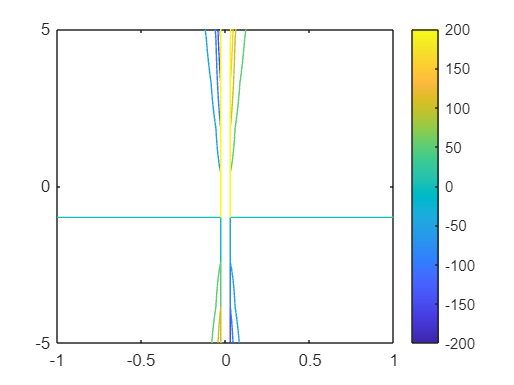

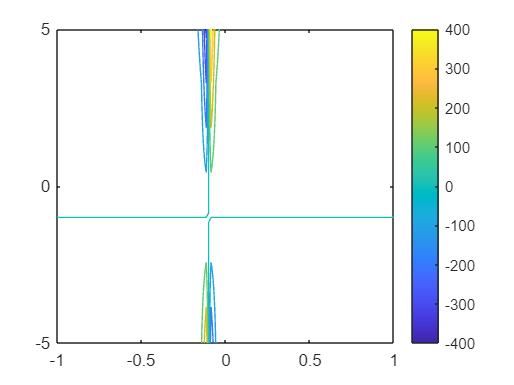

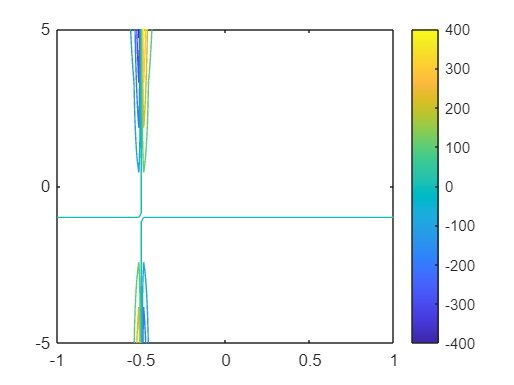

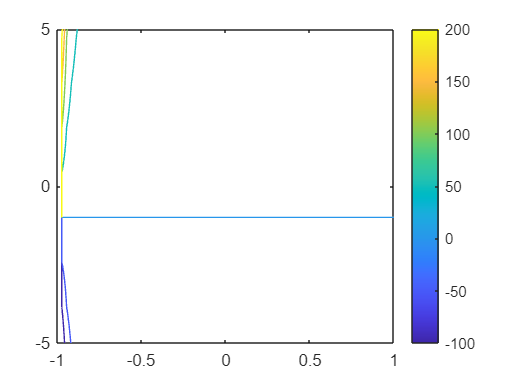


clear all
syms betaReal betaImag L_star real

alpha = (1 + betaReal) / (L_star + betaImag);

for L = [0, .1, .5, 1]
    figure
    fcontour(subs(alpha,L_star,L),[-1 1 -5 5])
    colorbar
end